## 필터 설계

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Nyquist = Fs / 2;    % 나이퀴스트 주파수
Fstart = 1;         % 통과대역 주파수 (Hz)
Fend = 5;         % 통과대역 주파수 (Hz)

% FIR 필터 설계
order = 250; % 필터 차수
b = fir1(order, [Fstart/Nyquist,Fend/Nyquist], 'bandpass', kaiser(order+1, 0.5));

## 필터 응답 확인

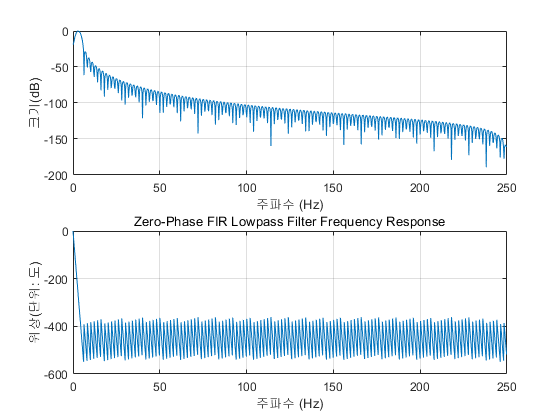

% 주파수 응답 플로팅
freqz(b, 1, 1024, Fs);
% 결과 표시
title('Zero-Phase FIR Lowpass Filter Frequency Response');

### 위상 응답 확인

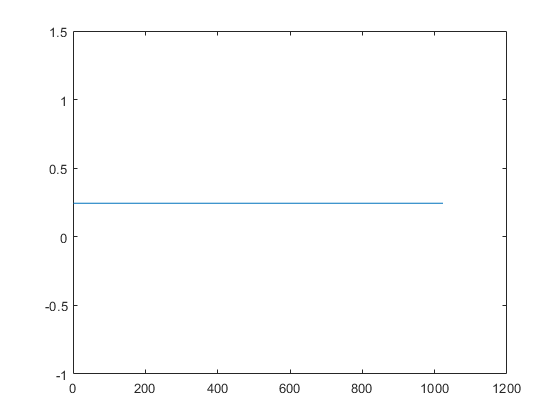

[h,w] = freqz(b, 1, 1024, Fs);
d = diff(w);
plot(d);

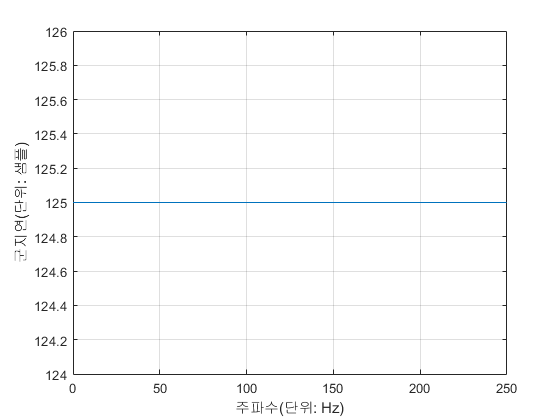

grpdelay(b, 1, 1024, Fs);

csvwrite("b.csv",b)